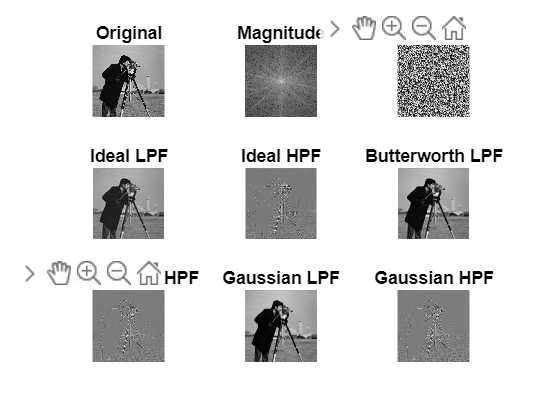

img = imread("cameraman.png");

F = fft2(double(img));
F_shifted = fftshift(F);

[M,N]=size(img);
DO=40;
h=zeros(M,N);

for u=1:M
    for v=1:N
        D=sqrt((u-M/2)^2+(v-N/2)^2);
        if D<=DO
            h(u,v)=1;
        end
    end
end

G=h.*F_shifted;
filtered_img=real(ifft2(ifftshift(G)));

h_high = zeros(M,N);
for u = 1:M
    for v = 1:N
        D = sqrt((u - M/2)^2 + (v - N/2)^2);
        if D > DO
            h_high(u,v) = 1;
        end
    end
end

G_high = h_high .* F_shifted;
filtered_high = real(ifft2(ifftshift(G_high)));

n=2;
H_b=zeros(M,N);
for u=1:M
    for v=1:N
        D=sqrt((u-M/2)^2+(v-N/2)^2);
        H_b(u,v)=1/(1+(D/DO)^(2*n));
    end
end

G_b=H_b.*F_shifted;
img_b=real(ifft2(ifftshift(G_b)));


H_bh = 1 - H_b;
G_bh = H_bh .* F_shifted;
img_bh = real(ifft2(ifftshift(G_bh)));


H_g = zeros(M,N);
for u = 1:M
    for v = 1:N
        D = sqrt((u - M/2)^2 + (v - N/2)^2);
        H_g(u,v) = exp(-(D^2)/(2*(DO^2)));
    end
end

G_g = H_g .* F_shifted;
img_g = real(ifft2(ifftshift(G_g)));


H_gh = 1 - H_g;
G_gh = H_gh .* F_shifted;
img_gh = real(ifft2(ifftshift(G_gh)));

figure;

subplot(3,3,1);
imshow(img); title("Original");

subplot(3,3,2);
imshow(log(abs(F_shifted)+1), []); title("Magnitude");

subplot(3,3,3);
imshow(angle(F_shifted), []); title("Phase");

subplot(3,3,4);
imshow(filtered_img, []); title("Ideal LPF");

subplot(3,3,5);
imshow(filtered_high, []); title("Ideal HPF");

subplot(3,3,6);
imshow(img_b, []); title("Butterworth LPF");

subplot(3,3,7);
imshow(img_bh, []); title("Butterworth HPF");

subplot(3,3,8);
imshow(img_g, []); title("Gaussian LPF");

subplot(3,3,9);
imshow(img_gh, []); title("Gaussian HPF");